clc
clear
close all

Load the X-ray dataset to get the phantom and pad it with zeros so that the image can be rotated without clipping.

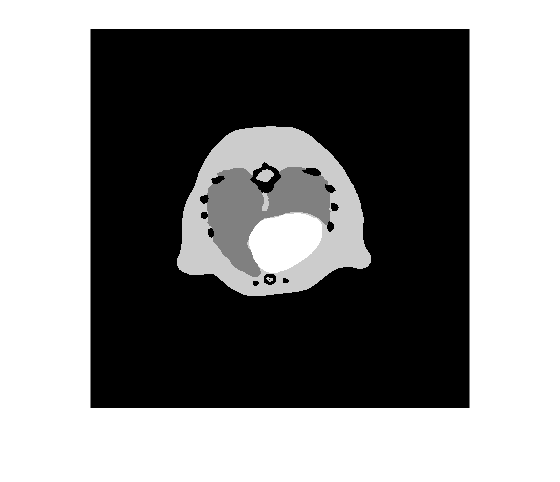

n_tissues=2;

pixel_size = 0.04;  % cm

data_size = [380,380,190]; %%i.e. a mouse-shaped cuboid with lateral cross-sectional size of 380 pixels, axial length of 190 pixels

density_map = zeros(data_size(1),data_size(2),data_size(3),n_tissues);

fid = fopen('digimouse_soft_tissue_sq.img');

density_map(:,:,:,1) = reshape(fread(fid, data_size(1)*data_size(2)*data_size(3),'float'),data_size);

fclose(fid);

fid = fopen('digimouse_bone_sq.img');

density_map(:,:,:,2) = reshape(fread(fid, data_size(1)*data_size(2)*data_size(3),'float'),data_size);

fclose(fid);

imshow(density_map(:,:,130,1))

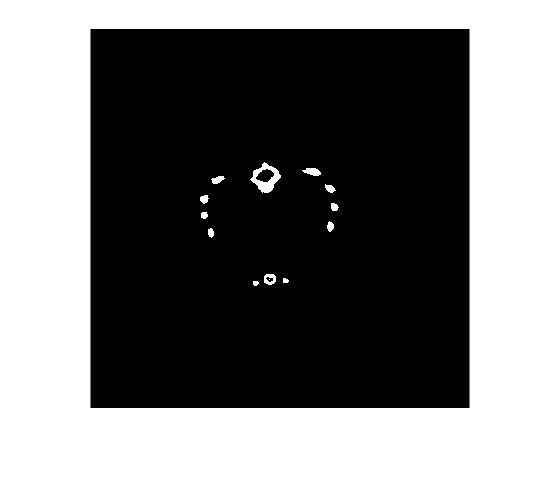

imshow(density_map(:,:,130,2))

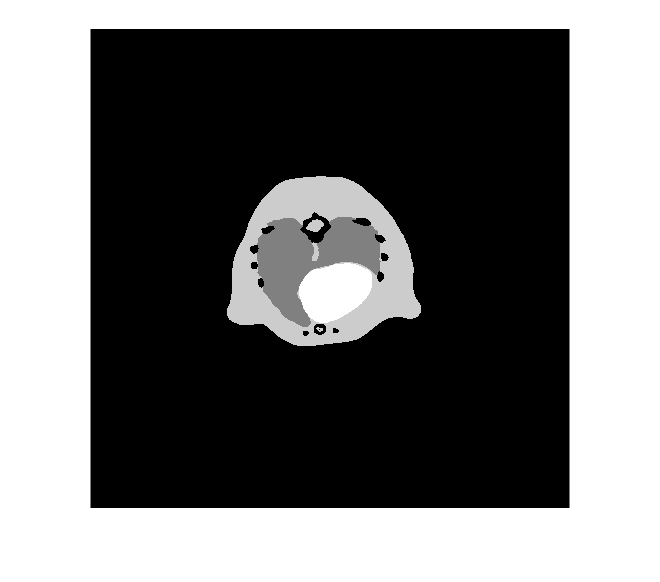

softissue=density_map(:,:,130,1);
boneissue=density_map(:,:,130,2);

padP = padarray(softissue, [50, 50]); %Pad the image as we will be rotating and cropping it later
imSize=size(padP);
imshow(padP)


startangle=1; %Set up the range of angles used to record SPECT projections
stopangle=360;
steps=360;
theta=startangle:((stopangle-startangle)/(steps-1)):stopangle; %Array of angles later used in function iRadon

Record projections of activity levels in the phantom in the case of zero gamma attenuation. Instead of rotating the detector, we rotate the object.

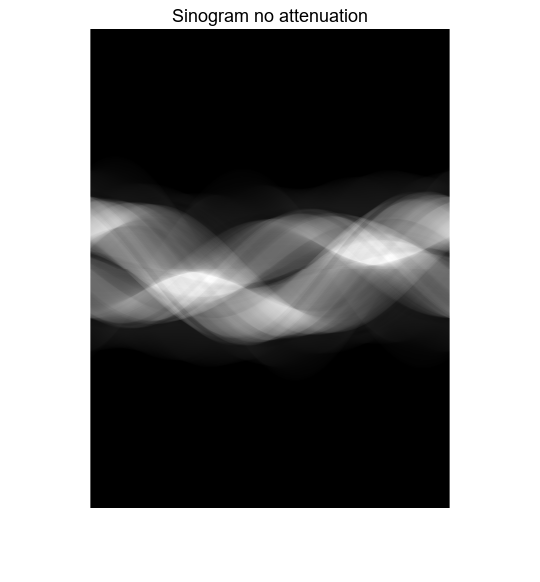

R = zeros(length(padP), steps); %R is the space for the sinogram
padP1=padP;
padP1(padP1==0.5)=1;
padP1(padP1~=1&padP1~=0)=0.1;
for k=1:steps
    R(:,k)=sum(imrotate(padP1, -startangle-(k-1)*((stopangle-startangle)/(steps-1)), 'bilinear', 'crop')); %Populate the sinogram. Instead of rotating the detector to +ve theta values, we are rotating the 'sample' through -ve theta. Then sum the columns.
end
imshow(R,[]); 
title('Sinogram no attenuation') 

Use sinogram for tomographic reconstruction.

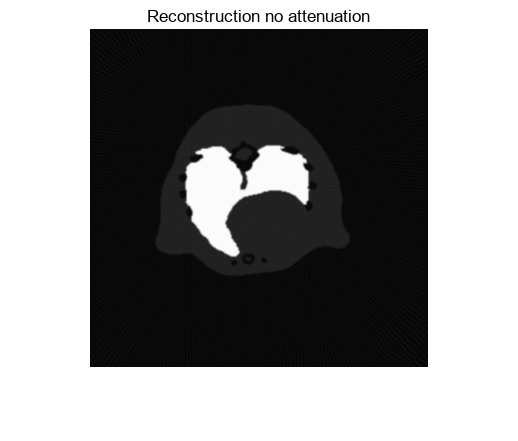

Recon=iradon(R,theta); %Perform inverse Radon transform
imshow(Recon, [])
title('Reconstruction no attenuation')

Assign an attenuation coefficient to all pixels in the object. This is defined per pixel length as the units are arbitrary.

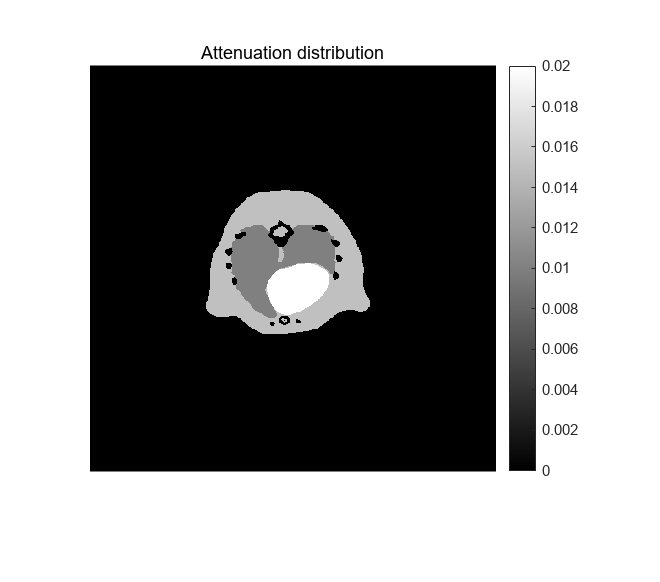

% This is the attenuation value per pixel length that the gamma photon passes through
% Set different absorption coefficients for the different dark inclusions
coeff= 0.01;
coeff2=0.015;
coeff3=0.02;
attencoeff=padP;
attencoeff(attencoeff>0&attencoeff<0.6)=coeff;
attencoeff(attencoeff>0.6&attencoeff<1)=coeff2;
attencoeff(attencoeff>1&attencoeff<1.6)=coeff3;

imshow(attencoeff, []); 
title('Attenuation distribution') 
colorbar

Assuming the detector is at the top of the sample, calculate the cumulative attenuation for each pixel in the image.

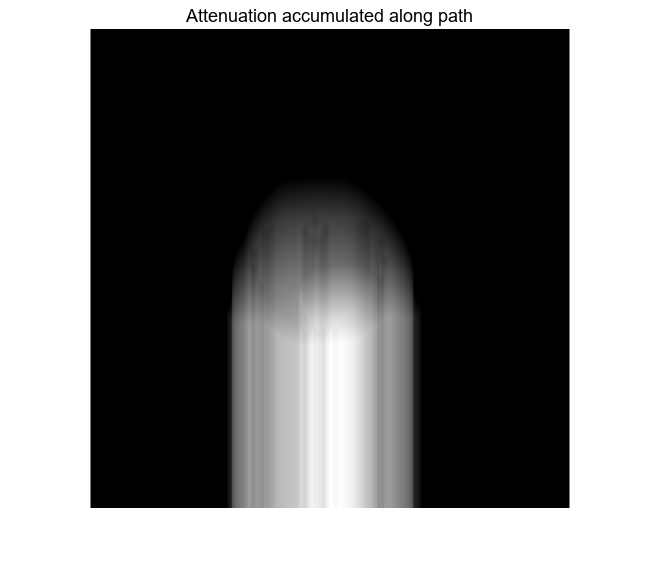

pathatten = zeros(imSize); %Matrix to hold the cumulative attenuation information for each pixel
for j=2:480
    pathatten(j,:)=attencoeff(j,:)+pathatten(j-1,:); %Starting from top pixel first, calculate the attenuation along the path from the pixel to the top of the image
end
imshow(pathatten, [])
title('Attenuation accumulated along path') 

Calculate the sinogram and tomographic reconstruction in the case of attenuation. This time both the activity level image and the attenuation image are rotated to calculate the projections.

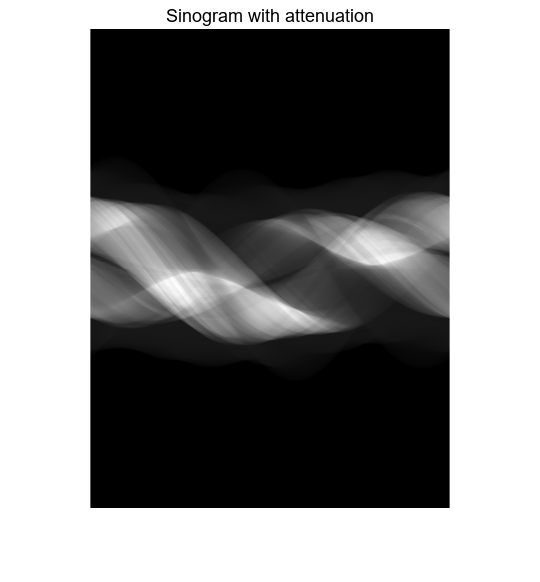

r = zeros(length(padP1), steps); %r is the space for the SPECT sinogram with attenuation

for k=1:steps
    pathattenrot = zeros(imSize); %For each rotation of the sample, start with clear path attenuation matrix
    attencoeffrot=imrotate(attencoeff, -startangle-(k-1)*((stopangle-startangle)/(steps-1)), 'bilinear', 'crop'); %Rotate the attenuation coefficient image
    for j=2:480
        pathattenrot(j,:)=attencoeffrot(j,:)+pathattenrot(j-1,:); %Calculate the attenuation along the path
    end
    r(:,k)=sum(imrotate(padP1, -startangle-(k-1)*((stopangle-startangle)/(steps-1)), 'bilinear', 'crop').*exp(-pathattenrot)); %Populate the sinogram. 
end
imshow(r, []); %Display the sinogram
title('Sinogram with attenuation') 

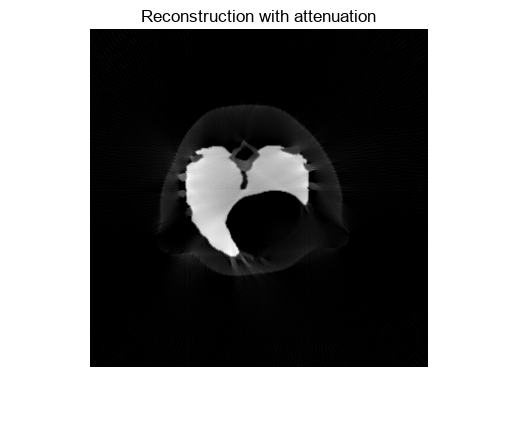


Reconatten=iradon(r,theta); %Perform inverse Radon transform
imshow(Reconatten, [0 max(max(Reconatten))]);
title('Reconstruction with attenuation') 